clc,clear,close all
syms fs f0 fd
R = 1 - (2*pi*fd/fs)/2;
w0 = (2*pi)*(f0/fs)

$$w0 = \frac{2\,\pi \,f_{0}}{\mathrm{fs}}$$

G = (1-R)*sqrt(1-2*R*cos(2*w0)+R^2)

$$G = \frac{\pi \,\mathrm{fd}\,\sqrt{{\left(\frac{\pi \,\mathrm{fd}}{\mathrm{fs}}-1\right)}^{2}+\cos\left(\frac{4\,\pi \,f_{0}}{\mathrm{fs}}\right)\,\left(\frac{2\,\pi \,\mathrm{fd}}{\mathrm{fs}}-2\right)+1}}{\mathrm{fs}}$$

a1 = -2*R*cos(w0)

$$a1 = \cos\left(\frac{2\,\pi \,f_{0}}{\mathrm{fs}}\right)\,\left(\frac{2\,\pi \,\mathrm{fd}}{\mathrm{fs}}-2\right)$$

a2 = R^2;

$$a2 = {\left(\frac{\pi \,\mathrm{fd}}{\mathrm{fs}}-1\right)}^{2}$$

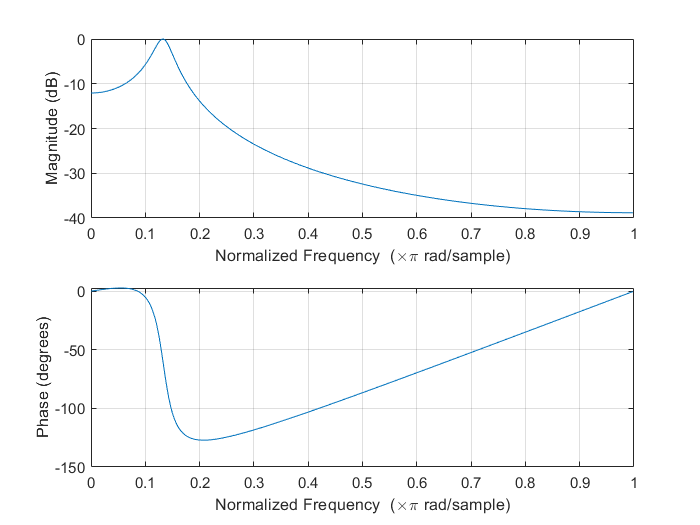


[G,a1,a2] = ResonatorFilter(30*10^6,2*10^6,0.5*10^6);
freqz([G 0 0],[1 a1 a2]);